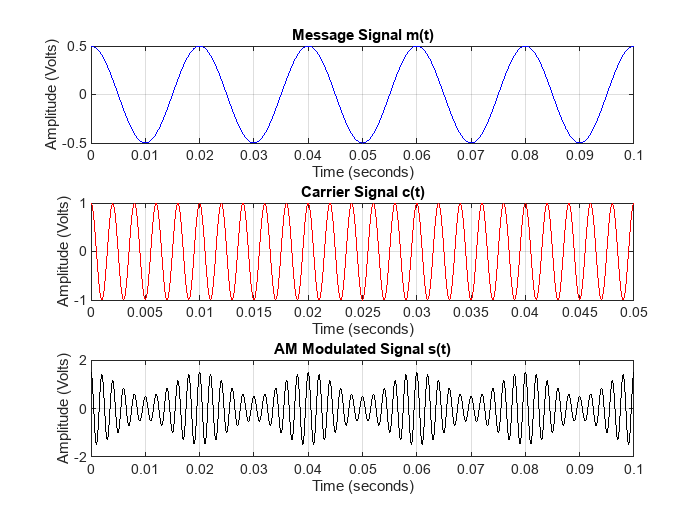

% Parameters
Fs = 10000;          
f_message = 50;      
A_message = 0.5;     
f_carrier = 500;     
A_carrier = 1;       
mod_index = 1;      
% Time vector for 1 second duration
t = 0:1/Fs:1;
% Message signal m(t) = Am * cos(2*pi*fm*t)
m_t = A_message * cos(2 * pi * f_message * t);
% Carrier signal c(t) = Ac * cos(2*pi*fc*t)
c_t = A_carrier * cos(2 * pi * f_carrier * t);
% AM modulated signal s(t) = (Ac + m(t)) * cos(2*pi*fc*t)
s_t = (A_carrier + m_t) .* cos(2 * pi * f_carrier * t);
% Plot the signals
figure;
subplot(3,1,1);
plot(t, m_t, 'b');
title('Message Signal m(t)');
xlabel('Time (seconds)');
ylabel('Amplitude (Volts)');
grid on;
xlim([0 0.1]); 
subplot(3,1,2);
plot(t, c_t, 'r');
title('Carrier Signal c(t)');
xlabel('Time (seconds)');
ylabel('Amplitude (Volts)');
grid on;
xlim([0 0.05]); 
subplot(3,1,3);
plot(t, s_t, 'k');
title('AM Modulated Signal s(t)');
xlabel('Time (seconds)');
ylabel('Amplitude (Volts)');
grid on;
xlim([0 0.1]); 